## Final Project

Annie and Samuel

Final Project, Project Bank, Question 1

Smart Home Energy Dashboard

Tasks:

- Create or obtain a dataset of hourly (or daily) energy usage (kWh) over 3-6 weeks.

- Clean data (missing values, unit consistency) and compute weekly totals and peak hours.

- Create: (i) time-series plot, (ii) histogram of usage, (iii) weekday vs weekend comparison, (iv) summary dashboard.

- Propose two interventions (behavior or scheduling) and quantify potential impact with simple 'what-if' changes.

Part 1:

The data set to be used for this model was created in Excel. The data lasts for six weeks, and starts on a Monday. All the usage data is in kWh and there are no days missing. 

table = readtable('SmartHomeEngeryData.xlsx'); % importing the data spreadsheet
display(table)

table = 42×2 table
    Days    Energy_Usage1
    ____    _____________

      1          28      
      2          28      
      3          28      
      4          28      
      5          30      
      6          32      
      7          33      
      8          28      
      9          28      
     10          28      
     11          28      
     12          29      
     13          31      
     14          32      
     15          28      
     16          28      


Part 2:

Since the data was created, and everything is already consistent, in this section the weekly totals of every usage is computed along with the peak days of usage. 

T = table2array(table); % converting the table to an array to make it easier to work with
for k = 1:6 % creating a for loop to calculate the average usage values for each week
    mean(T((k*7-6):k*7,2)) % using the mean function to find the average usage values per week
end % end of loop

ans = 29.5714

ans = 29.1429

ans = 29.4286

ans = 29.4286

ans = 29.2857

ans = 24.7143


for k = 1:6 % creating a loop to calculate the maximum usage values for each week
    max(T((k*7-6):k*7,2)) % function for finding the max values, with a return of what the max values are
end % end of loop

ans = 33

ans = 32

ans = 33

ans = 33

ans = 33

ans = 30

Part 3:

Creating histograms, graphs, and comparing the data

WeekEnd = [];% creating an array to separate out the weekend usage values from the table
x = 1; % placement variable for placing each value in the new array
while x <= 12 % while the array is smaller that its end size of 12
    k = 1;% value to denote which week data is being pulled from
    while k <= 6 % while the week value is less than or equal to six
        n = 1; % value to denote which day data is being pulled from
        while n >= 0 % while the day value is greater than zero, with a total of two values
            WeekEnd(x) = T(k*7-n,2); % pull data from the original array
            n = n - 1; % decrease day value by one 
            x = x + 1; % increase placement values by one
        end % end day loop
        k = k + 1; % increase week value by one
    end % end week loop 
end % end WeekDay loop

WeekDay = [];% creating an array to separate out the weekday usage values from the table
x = 1; % placement variable for placing each value in the new array
while x <= 12 % while the array is smaller that its end size of 30
    k = 1;% value to denote which week data is being pulled from
    while k <= 6 % while the week value is less than or equal to six
        n = 6; % value to denote which day data is being pulled from
        while n >= 2 % while the day value is greater than two, with a total of seven values
            WeekDay(x) = T(k*7-n,2); % pull data from the original array
            n = n - 1; % decrease day value by one 
            x = x + 1; % increase placement values by one
        end % end day loop
        k = k + 1; % increase week value by one
    end % end week loop 
end % end WeekDay loop

fprintf('Power Usage Summary:')

Power Usage Summary:

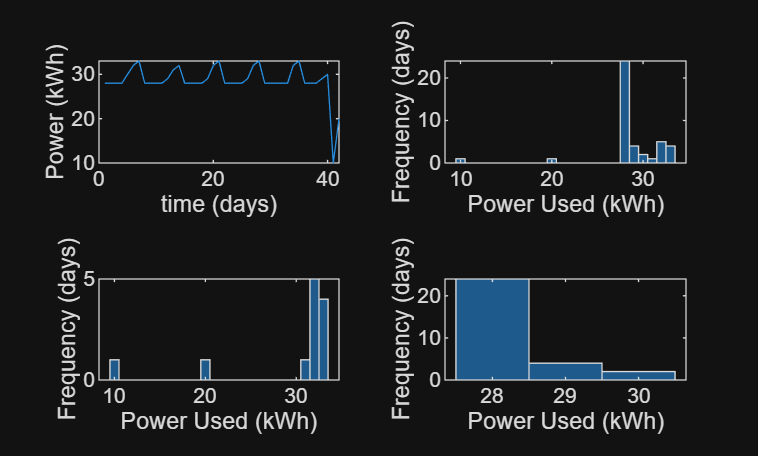


tiledlayout(2,2); % creating tiled loayout for the final summary appearence

% time-series plot
nexttile % making sure plot appears in tiled layout
plot(T(:,1), T(:, 2)); % creating a graph of usage over time. 
xlabel('time (days)'); % x axis label
ylabel('Power (kWh)'); % y axis label

% histogram
nexttile % making sure plot appears in tiled layout
histogram(T(:,2)); % creating a histogram of power usage
xlabel('Power Used (kWh)'); % labeling horizontal axis of the histogram
ylabel('Frequency (days)'); % labeling the vertical axis of the histogram

% weekday vs weekend
nexttile % making sure plot appears in tiled layout
histogram(WeekEnd); % create a histogram for the weekend power usages, the color is blue
xlabel('Power Used (kWh)');
ylabel('Frequency (days)');

nexttile % making sure plot appears in tiled layout
histogram(WeekDay); % create a histogram for the weekday power usages, the color is red
xlabel('Power Used (kWh)');
ylabel('Frequency (days)');

Part 4:

Ways to decrease energy consumption.

The power consumption is clearly higher on weekend than weekdays. Due to this observation it can be assumed that the occupants of the house are home more on the weekends. In order to decrease energy consumption overall, the occupants would have to decrease acitivities that i use electricity. Without knowing more specifics about where the power is being used, further advisement cannot be made. 